# Regression

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Regression')

## Calculate B's

weight = [55,61,67,83,65,82,70,58,65,61];
height = [140,150,152,220,190,195,175,130,155,160];
B1 = sum((weight - mean(weight)) .* (height - mean(height))) / sum((weight - mean(weight)).^2)

B1 = 2.6069

B0 = mean(height) - B1 * mean(weight)

B0 = -7.1769

## Bivariate Prediction

weight_bob = 80;
height_bob = B0 + B1 * weight_bob

height_bob = 201.3711

## Bivariate - Standard Error of Estimate

SE = sqrt(sum((height - (B0 + B1 .* weight)).^2) / (length(weight) - 2))

SE = 14.1141

## Correlation Coefficient (r)

r = sum((weight - mean(weight)) .* (height - mean(height))) / (sqrt(sum((weight - mean(weight)).^2)) * sqrt(sum((height - mean(height)).^2)))

r = 0.8786

corr(height', weight')

ans = 0.8786

## Coefficient of Determination (r^2)

rsquared = corr(height', weight')^2

rsquared = 0.7720

## Bivariate Regression - Significance Test Cont'd

N = length(weight);
Fstat0 = (r*r*(N-2)) / (1-(r*r))

Fstat0 = 27.0896

pval0 = 1 - cdf('f', Fstat0, 1, N-2)

pval0 = 8.1763e-04

dataTable2 = table(height', weight', 'VariableNames', {'height', 'weight'})

dataTable = 10×2 table
    height    weight
    ______    ______
     140        55  
     150        61  
     152        67  
     220        83  
     190        65  
     195        82  
     175        70  
     130        58  
     155        65  
     160        61  

lmModel = fitlm(dataTable2, 'weight~height')

lmModel = Linear regression model:
    weight ~ 1 + height

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)     17.332       9.6037    1.8048       0.10876
    height         0.29615     0.056899    5.2048    0.00081763

Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 4.76
R-squared: 0.772,  Adjusted R-Squared: 0.744
F-statistic vs. constant model: 27.1, p-value = 0.000818

lmModel.Coefficients.Estimate(1) % B_0, coefficient

ans = 17.3322

lmModel.Coefficients.Estimate(2) % B_1, coefficient

ans = 0.2961

lmModel.Coefficients.pValue(2) % p-value

ans = 8.1763e-04

lmModel.Rsquared % r^2 of model 

ans = struct with fields:
    Ordinary: 0.7720
    Adjusted: 0.7435

## Regression - Nonlinear

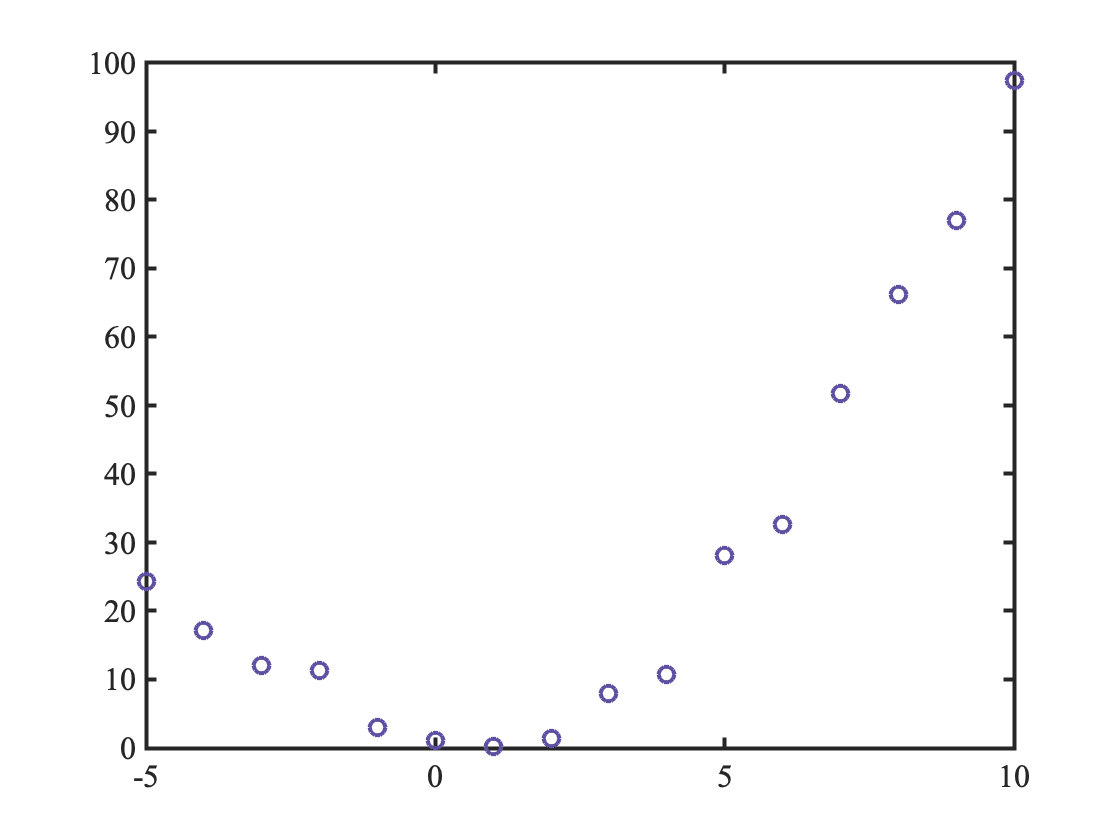

X = [-5,-4,-3,-2,-1,0,1,2,3,4,5,6,7,8,9,10]';
y = X.^2 + normrnd(0,3, [16 1]);
figure();
plot(X,y,'o', 'markersize', 8);

dataTable2 = table(X, y, 'variablenames', {'X', 'y'}); 
m2 = fitlm(dataTable2, 'y~X')

m2 = Linear regression model:
    y ~ 1 + X

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________
    (Intercept)     15.818     5.8187    2.7185      0.016644
    X               4.7287     1.1096    4.2617    0.00079009

Number of observations: 16, Error degrees of freedom: 14
Root Mean Squared Error: 20.5
R-squared: 0.565,  Adjusted R-Squared: 0.534
F-statistic vs. constant model: 18.2, p-value = 0.00079

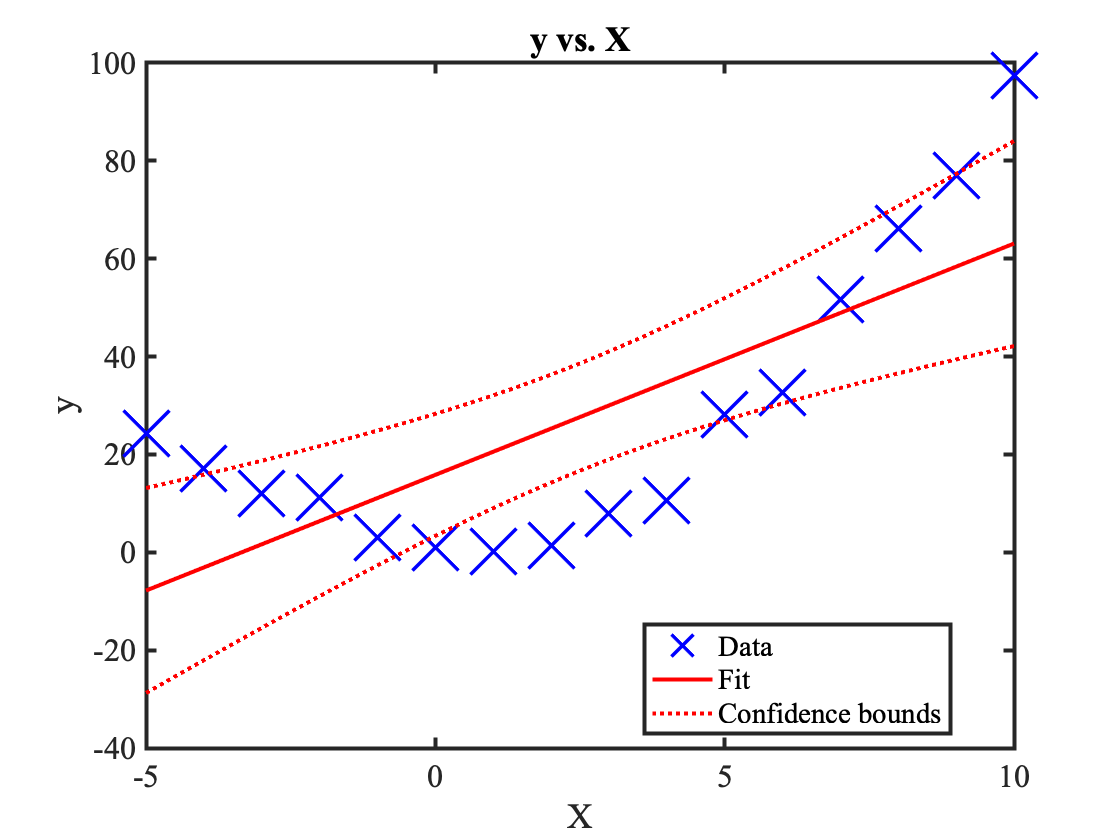

plot(m2)

Xsquared = X.^2;
dataTable0 = table(Xsquared, y, 'variablenames', {'Xsquared', 'y'}); 
m0 = fitlm(dataTable0, 'y~Xsquared')

m0 = Linear regression model:
    y ~ 1 + Xsquared

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)     1.0207       1.1024    0.9259       0.37019
    Xsquared       0.96796     0.027184    35.608    3.8998e-15

Number of observations: 16, Error degrees of freedom: 14
Root Mean Squared Error: 3.24
R-squared: 0.989,  Adjusted R-Squared: 0.988
F-statistic vs. constant model: 1.27e+03, p-value = 3.9e-15

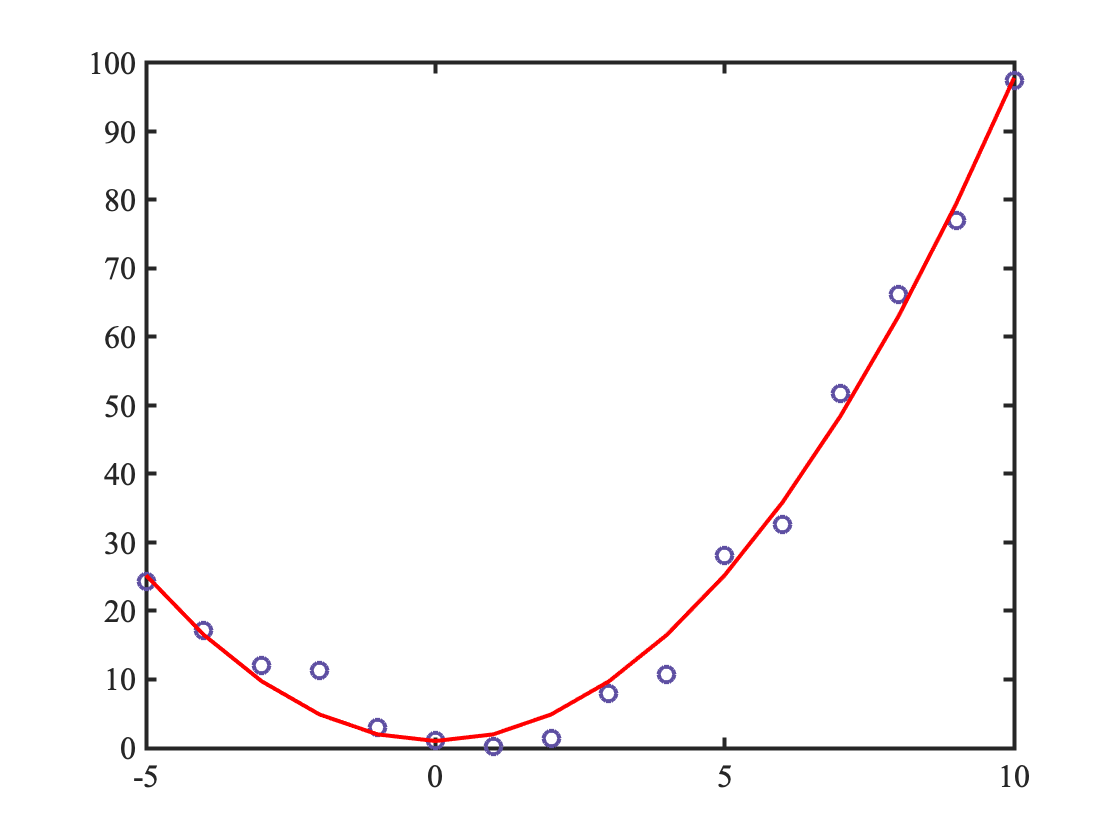

yfit = m0.predict(Xsquared);
figure();
plot(X,y,'o', 'markersize', 8);
hold on 
plot(X,yfit,'r-')

## Multiple Regression